# Interpolation of mean altitude of flight

Load data

clear all; addpath('./functions/');

Other

load('./data/dc_corr.mat','dc');  
load('data/Density_inference.mat','data')
load('./data/BelowRadarMPS.mat');
load('coastlines.mat')
Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );

dens_lim=1; %bird/km^3 Minimum density to keep data
alt_mean = nan(numel(dc(1).time),  numel(dc));
for i_d=1:numel(dc)
    tmp = dc(i_d).dens3;
    tmp(:,1:dc(i_d).scatter_lim-1) = mean(MPS{i_d}(:,1:dc(i_d).scatter_lim-1,:),3);
    tmp = tmp .* repmat(min(max(dc(1).alt-dc(i_d).heightDEM,0),200)/200,size(tmp,1),1);
    
    tmp(any(isnan(tmp),2),:) = nan;
    tmp(sum(tmp(:,dc(i_d).scatter_lim:end)*.2,2)<dens_lim,:) = nan;
    alt_mean(:,i_d) = sum(tmp .* repmat(dc(1).alt,size(tmp,1),1),2) ./ sum(tmp,2);
    
    % locate altitude with highest value
    [~,id] = max(tmp,[],2);
    alt_max(:,i_d) = dc(1).alt(id);
    
% Compute quantile instead of mean.    
%     tmp2 = cumsum(tmp,2)./sum(tmp,2);
%     for i_t = 1:size(tmp,1)
%         id = diff(tmp2(i_t,:))>0
%         if ~isnan(tmp2(i_t,1))
%             median_alt(i_t) = interp1(tmp2(i_t,id),dc(i_d).alt(id),.5);
%         end
%     end
end

Remove nan data to be same size as data

alt_mean(data.id_t,:)=[];
alt_mean(data.NNT<-1 | data.NNT>1)=nan;

Normalized with DEM

altn=alt_mean-repmat(data.heightDEM',size(alt_mean,1),1);

## Histogram 

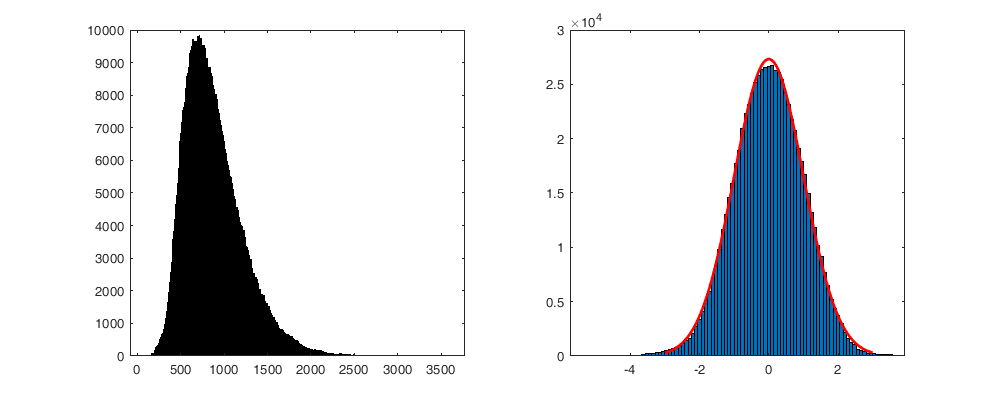

altt = (log(altn)-nanmean(log(altn(:)))) / nanstd(log(altn(:)));

figure('position',[0 0 1000 400]); 
subplot(1,2,1); histogram(altn);
subplot(1,2,2); histfit(altt(:),100); 

Average Daily

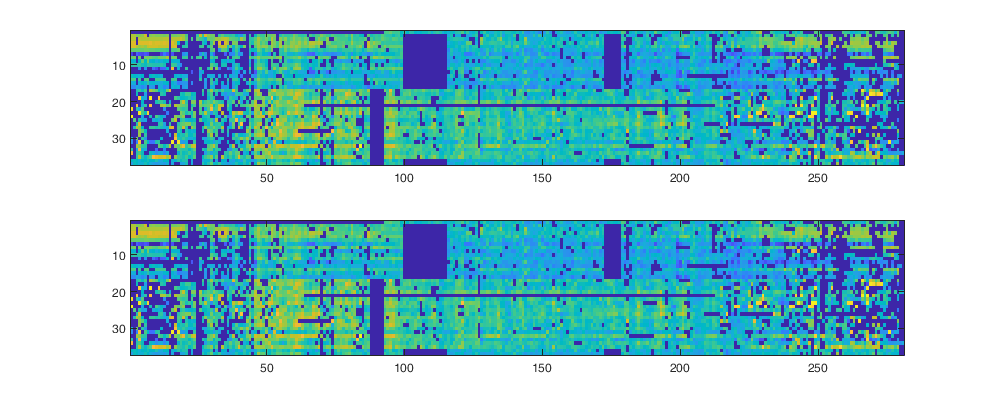

amulti.t = data.day;
amulti.r = 1:data.nrad;
[amulti.R,amulti.T]=meshgrid(amulti.r,amulti.t);

G = findgroups(data.day_id);
amulti.M = splitapply(@nanmean,altt,G);
amulti.isnan = isnan(amulti.M);

figure('position',[0 0 1000 400]); hold on;
subplot(2,1,1); imagesc(amulti.M')
subplot(2,1,2); imagesc(amulti.M')

Block décomposition

amulti.b = nan(size(amulti.t));
for i_b=1:numel(data.block.date)
    if i_b==numel(data.block.date)
        amulti.b(amulti.t>=data.block.date(i_b) | amulti.t<data.block.date(1)) = i_b;
    else
        amulti.b(amulti.t>=data.block.date(i_b) & amulti.t<data.block.date(i_b+1)) = i_b;
    end
end
amulti.B = repmat(amulti.b,1,data.nrad);
data.day_b = amulti.b;

amulti.poly_t_degree=0;
amulti.poly_d_degree=1;

X = trend(amulti.T,data.lat(amulti.R),data.lon(amulti.R),amulti.poly_t_degree,amulti.poly_d_degree);

amulti.f_trend = @(t,lat,lon,beta) reshape(trend(t(:),lat(:),lon(:),amulti.poly_t_degree,amulti.poly_d_degree) * beta(:), size(t));

amulti.M_n = nan(size(amulti.M)); amulti.Mvs_n = amulti.M_n;
amulti.beta = nan(amulti.poly_t_degree+ (amulti.poly_d_degree+1)^2,numel(data.block.date));

We loop over all block...

for i_b=1:numel(data.block.date)
    id = find(~amulti.isnan & amulti.B==i_b);
    amulti.beta(:,i_b) = ( X(id,:)' * X(id,:) ) \ (X(id,:)' * amulti.M(id) );
    amulti.M_n(id) = amulti.M(id)-amulti.f_trend(amulti.T(id),data.lat(amulti.R(id)),data.lon(amulti.R(id)),amulti.beta(:,i_b));
end

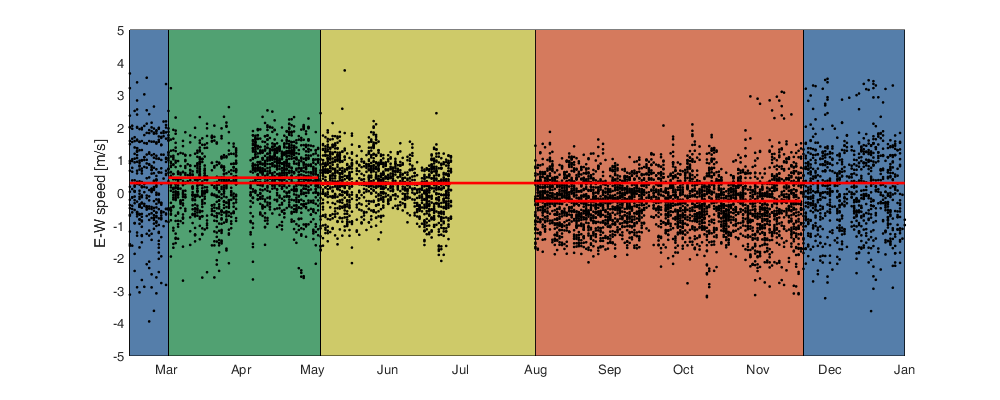

figure('position',[0 0 1000 400]); hold on
for i_b=1:numel(data.block.date)-1
    fill([data.block.date(i_b) data.block.date(i_b) data.block.date(i_b+1) data.block.date(i_b+1)],[5 -5 -5 5],data.block.col(i_b,:))
end
fill([min(data.day) min(data.day) data.block.date(1) data.block.date(1)],[5 -5 -5 5],data.block.col(4,:))
fill([data.block.date(end) data.block.date(end) max(data.day) max(data.day) ],[5 -5 -5 5],data.block.col(4,:))
plot(amulti.T(:),amulti.M(:),'.k'); 
for i_b=1:numel(data.block.date)
    id = find(~amulti.isnan & amulti.B==i_b);
    t_tmp = sort(unique(amulti.T(id)));
    plot(t_tmp, amulti.f_trend(t_tmp,mean(data.lat(amulti.R(id)))*ones(numel(t_tmp),1),mean(data.lon(amulti.R(id)))*ones(numel(t_tmp),1), amulti.beta(:,i_b)),'-r','Linewidth',2)
end
ylabel('E-W speed [m/s]'); datetick('x'); axis tight;

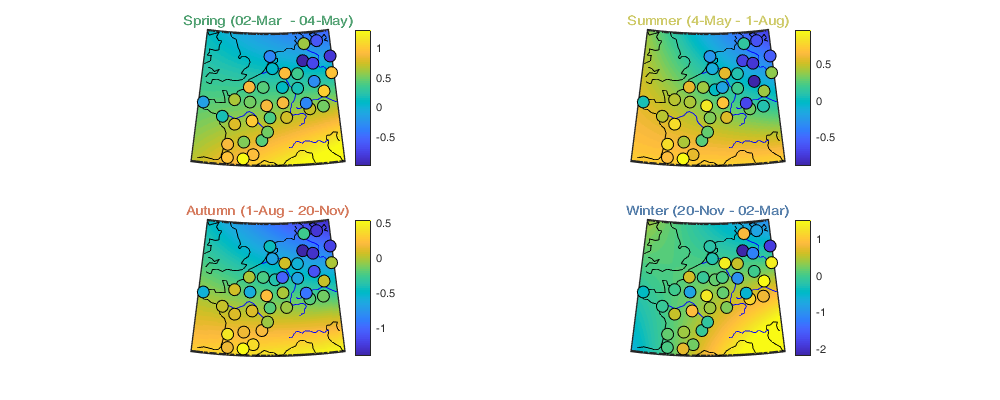

figure('position',[0 0 1000 400]); hold on; 
[LAT, LON] = meshgrid(floor(min(data.lat)):.1:ceil(max(data.lat)),floor(min(data.lon)):.1:ceil(max(data.lon)));
for i_b=1:numel(data.block.date)
    id = find(~amulti.isnan & amulti.B==i_b);
    subplot(2,2,i_b,'Color',data.block.col(i_b,:)); hold on; h=worldmap([floor(min(data.lat)) ceil(max(data.lat))], [floor(min(data.lon)) ceil(max(data.lon))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    surfm(LAT,LON,amulti.f_trend(mean(amulti.T(id))*ones(size(LAT)),LAT,LON,amulti.beta(:,i_b))) 
    plotm(coastlat, coastlon,'k'); geoshow('worldrivers.shp','Color', 'blue')
    [G,tmp]=findgroups(amulti.R(id));
    tmp2 = splitapply(@mean,amulti.M(id),G);
    scatterm(data.lat(tmp),data.lon(tmp),80,tmp2,'filled','MarkerEdgeColor','k'); 
    title(data.block.date_str{i_b},'Color',data.block.col(i_b,:) ); caxis([min(tmp2) max(tmp2)]); colorbar
end

clear LAT LON T t_tmp tmp* G X id i_b h 

## Covariance Multi

cov.d=[0 1 150 200 300 400 500 750 1000 2000];
cov.t=[0 1 2 3 4 5 10 20];
[cov.D,cov.T] = meshgrid(cov.d(1:end-1)+diff(cov.d)/2,cov.t(1:end-1));

cov.D_emp=nan(size(cov.D,1),size(cov.D,2),numel(data.block.date)-1);
cov.T_emp = cov.D_emp;
cov.emp_grid = nan(size(cov.D));

cov.nb=nan(numel(data.block.date)-1,1);
for i_b=1:numel(data.block.date)
    id = find(~amulti.isnan & amulti.B==i_b);
    cov.nb(i_b)=sum(id(:));
    Dtime=squareform(pdist(amulti.T(id)));
    Ddist=squareform(pdist([data.lat(amulti.R(id)) data.lon(amulti.R(id))],@lldistkm));
    
    cov_emp = bsxfun(@times, amulti.M_n(id)', amulti.M_n(id));
    
    for i_t=1:numel(cov.t)-1
        for i_d=1:numel(cov.d)-1
            id = Dtime>=cov.t(i_t) & Dtime<cov.t(i_t+1) & Ddist>=cov.d(i_d) & Ddist<cov.d(i_d+1);
            cov.D_emp(i_t,i_d,i_b) = nanmean(Ddist(id));
            cov.T_emp(i_t,i_d,i_b) = nanmean(Dtime(id));
            cov.emp_grid(i_t,i_d,i_b) = nanmean( cov_emp(id) );
        end
    end
end

Figure

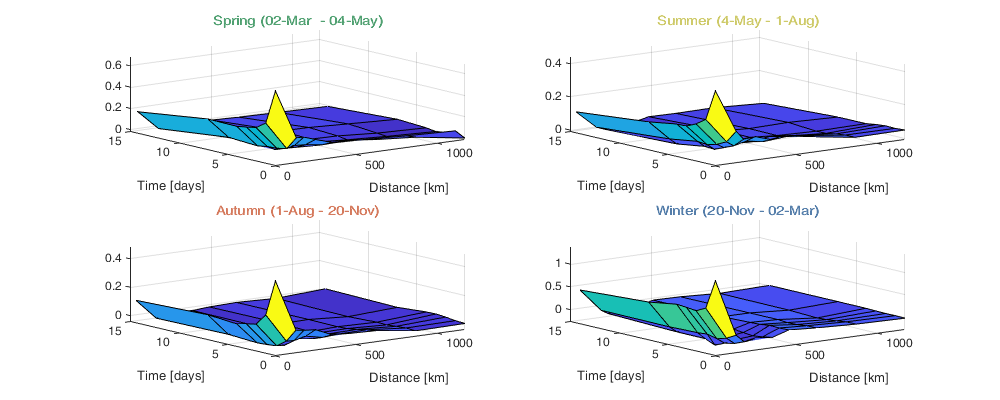

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,2,i_b); surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
end

## Covariance function fit

Gneiting_fit = @(parm,i_b) parm(1)*(cov.D_emp(:,:,i_b)==0 & cov.T_emp(:,:,i_b)==0) + parm(2).*Gneiting(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),parm(3),parm(4),parm(5),parm(6),parm(7));

parm0 =[0 20 500 5 .5 .5 .5 ]';
parm_min=[0 0 0.0001 0 0 0 0 ]';

for i_b=1:numel(data.block.date)
    id = find(~amulti.isnan & amulti.B==i_b);
    parm_max=[nancov(amulti.M_n(id)) nancov(amulti.M_n(id)) 3000 10 1 1 1 ]';
    rmse = @(parm) nansum(nansum( ( abs(Gneiting_fit(parm,i_b) - cov.emp_grid(:,:,i_b)) ) )); % 1000*max(cov.emp_grid(:,:,i_b),0).*
    amulti.cov.parm(:,i_b) = fmincon(rmse,parm0,[],[],[1 1 0 0 0 0 0],nancov(amulti.M_n(id)),parm_min,parm_max,[],optimoptions('fmincon','Display','off'));
end

amulti.cov.C = @(D,T,i_b) amulti.cov.parm(1,i_b)*(D==0 & T==0) + amulti.cov.parm(2,i_b).*Gneiting(D,T,amulti.cov.parm(3,i_b),amulti.cov.parm(4,i_b),amulti.cov.parm(5,i_b),amulti.cov.parm(6,i_b),amulti.cov.parm(7,i_b));

 Illustration of the fitted covariance function

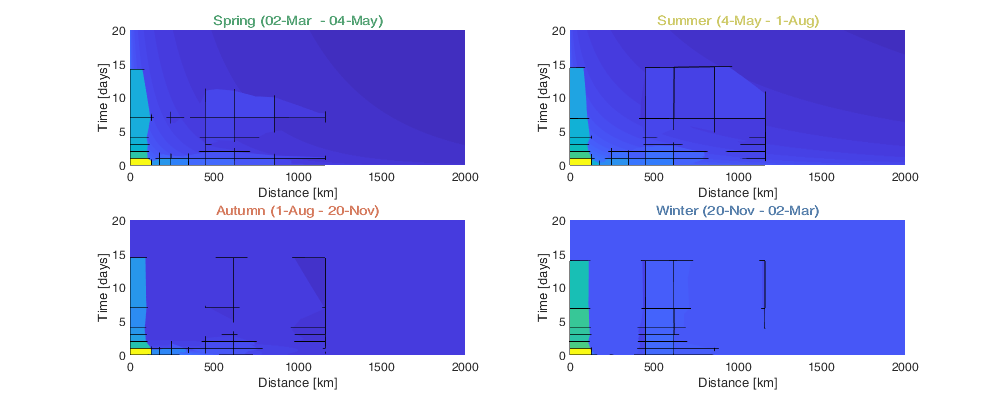

[tmpD,tmpT] = meshgrid(cov.d(1):1:cov.d(end),cov.t(1):0.1:cov.t(end));

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,2,i_b); hold on
    s=surf(tmpD,tmpT,amulti.cov.C(tmpD, tmpT,i_b)); s.EdgeColor='none';
    surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
end

Clear all un-necessary variable

clear C cov* Ddist Dtime Gneiting_fit h i* L* parm* rmse s tmp*

## Intra-night scale

At the intra-night scale, we model the the fluctuation around the multi-night scale

wintra.Ius = wu-amulti.M(data.day_id,:);
wintra.Ivs = wv-amulti.Mvs(data.day_id,:);
wintra.isnan = isnan(wintra.Ius);

Block decomposition

wintra.b = nan(size(data.time));
for i_b=1:numel(data.block.date)
    if i_b==numel(data.block.date)
        wintra.b(datenum(data.time)>=data.block.date(4) | datenum(data.time)<data.block.date(1)) = i_b;
    else
        wintra.b(datenum(data.time)>=data.block.date(i_b) & datenum(data.time)<data.block.date(i_b+1)) = i_b;
    end
end
wintra.B = repmat(wintra.b,1,data.nrad);

In addition to present a trend of the mean, the intra-night components also contains a non-stationarity of variance along the night (see figure below). We fit another polynomial function to normalize the variance


$$\sigma_I \left(t,\mathit{\mathbf{s}}\right)=\sum_{i=i}^{10} b_i \textrm{NNT}\left(t,\mathit{\mathbf{s}}\right)$$


wintra.poly_degree=4;
X=bsxfun(@power,data.NNT(:),wintra.poly_degree:-1:0);
wintra.f_trend = @(t,beta_v) reshape(bsxfun(@power,t(:),wintra.poly_degree:-1:0) * beta_v(:),size(t));

We will then compute the detrended value of the multi-night scale componenent

fintra_Ius_var = nan(size(wintra.Ius));
fintra_Ivs_var = fintra_Ius_var;
wintra.beta = nan(wintra.poly_degree+1,numel(data.block.date));
wintra.beta_v = nan(wintra.poly_degree+1,numel(data.block.date));

We loop over all block...

for i_b=1:numel(data.block.date)
    id = wintra.B==i_b & ~wintra.isnan;
    wintra.beta(:,i_b) = (X(id,:)'*X(id,:))\(X(id,:)'*wintra.Ius(id).^2);
    wintra.beta_v(:,i_b) = (X(id,:)'*X(id,:))\(X(id,:)'*wintra.Ivs(id).^2);
    fintra_Ius_var(id) = wintra.f_trend(data.NNT(id),wintra.beta(:,i_b));
    fintra_Ivs_var(id) = wintra.f_trend(data.NNT(id),wintra.beta_v(:,i_b));
end

Illustration

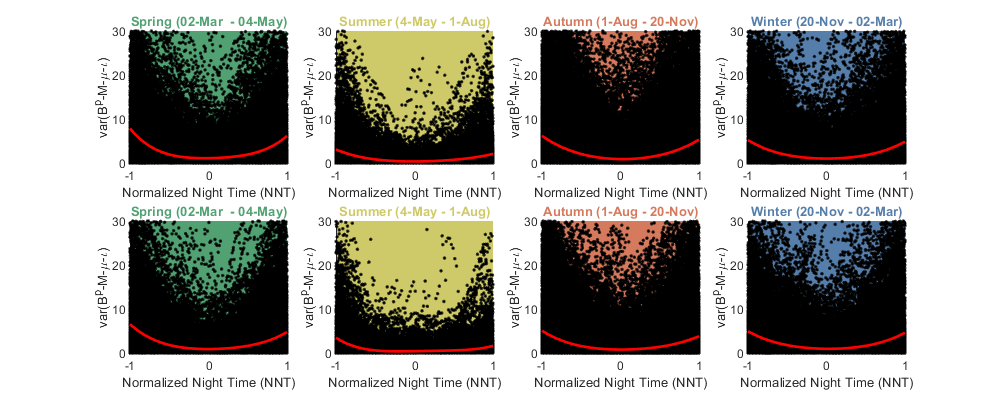

NNT_axis=-1:.01:1;
figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    id = wintra.B==i_b & ~wintra.isnan;
    subplot(2,4,i_b,'color',data.block.col(i_b,:)); hold on
    plot(data.NNT(id),wintra.Ius(id).^2,'.k');
    plot(NNT_axis, wintra.f_trend(NNT_axis,wintra.beta(:,i_b)),'-r','linewidth',2);
    title(data.block.date_str{i_b},'color',data.block.col(i_b,:)); 
    subplot(2,4,i_b,'color',data.block.col(i_b,:)); 
    xlabel('Normalized Night Time (NNT)'); ylabel('var(B^p-M-\mu-\iota)');ylim([0 30]); xlim([-1 1])
    
    subplot(2,4,4+i_b,'color',data.block.col(i_b,:)); hold on
    plot(data.NNT(id),wintra.Ivs(id).^2,'.k');
    plot(NNT_axis, wintra.f_trend(NNT_axis,wintra.beta_v(:,i_b)),'-r','linewidth',2);
    title(data.block.date_str{i_b},'color',data.block.col(i_b,:)); 
    subplot(2,4,4+i_b,'color',data.block.col(i_b,:)); 
    xlabel('Normalized Night Time (NNT)'); ylabel('var(B^p-M-\mu-\iota)');ylim([0 30]); xlim([-1 1])
end

Finally, combining the polynomial of the curve and the correction for variance, we find the de-trended intra-night scale $I$

wintra.Ius_n = wintra.Ius(~wintra.isnan) ./ sqrt(fintra_Ius_var(~wintra.isnan));
wintra.Ivs_n = wintra.Ivs(~wintra.isnan) ./ sqrt(fintra_Ivs_var(~wintra.isnan));

clear X fintra_* NNT_axis i*

## 4.2 Covariance function of $I\left(t,\mathit{\mathbf{s}}\right)$

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

Ddist_sm = squareform(pdist([data.lat data.lon], @lldistkm));
tmp=repmat(1:data.nrad,data.ntime,1);
wintra.radar = tmp(~wintra.isnan);
tmp=repmat(data.day(data.day_id),1,data.nrad);
wintra.day = tmp(~wintra.isnan);
tmp=repmat(datenum(data.time),1,data.nrad);
wintra.time = tmp(~wintra.isnan);

cov.d=[0 1 100 150 200 250 300 600 1000];
cov.t=[0 .01 .02 .05 .07 .1 .2];
[cov.D,cov.T]=meshgrid(cov.d(1:end-1)+diff(cov.d)/2,cov.t(1:end-1)+diff(cov.t)/2);
cov.D_emp=nan(size(cov.D,1),size(cov.D,2),numel(data.block.date)); 
cov.T_emp=nan(size(cov.D_emp));
cov.emp_grid=nan(size(cov.D_emp));
cov.emp_grid_v=nan(size(cov.D_emp));

for i_b=1:numel(data.block.date)

    D = nan(1000000000,2);
    Did = zeros(1000000000,2,'uint32');
    i=0;
    for i_t=data.day(data.day_b==i_b)'
        id = find(wintra.day==i_t);
        tmp1 = [reshape(Ddist_sm(wintra.radar(id),wintra.radar(id)),[],1) reshape(squareform(pdist(wintra.time(id))),[],1)];
        tmp2 = [uint32(repmat(id,numel(id),1)) uint32(repelem(id,numel(id)))];
        
        B = tril(ones(numel(id)));
        id2=B(:)==1 & tmp1(:,1)<cov.d(end) & tmp1(:,2)<cov.t(end);
        D(i+(1:sum(id2)),:)=tmp1(id2,:);
        Did(i+(1:sum(id2)),:)=tmp2(id2,:);
        i=i+sum(id2);
    end
    D=D(1:i,:);
    Did=Did(1:i,:);

    
    for i_d=1:numel(cov.d)-1
        id1 = find(D(:,1)>=cov.d(i_d) & D(:,1)<cov.d(i_d+1));
        for i_t=1:numel(cov.t)-1
            id2 = id1(D(id1,2)>=cov.t(i_t) & D(id1,2)<cov.t(i_t+1));
            cov.emp_grid(i_t,i_d,i_b)= mean(wintra.Ius_n(Did(id2,1)) .* wintra.Ius_n(Did(id2,2)));
            cov.emp_grid_v(i_t,i_d,i_b)= mean(wintra.Ivs_n(Did(id2,1)) .* wintra.Ivs_n(Did(id2,2)));
            cov.D_emp(i_t,i_d,i_b) = nanmean(D(id2,1));
            cov.T_emp(i_t,i_d,i_b) = nanmean(D(id2,2));
        end
    end
end

Figure

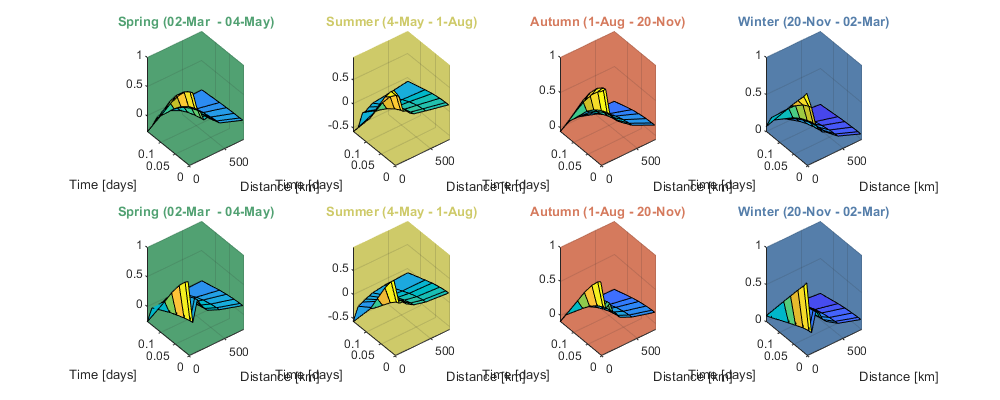

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,4,i_b); surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    subplot(2,4,i_b,'color',data.block.col(i_b,:)); 
    
    subplot(2,4,4+i_b); surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid_v(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    subplot(2,4,4+i_b,'color',data.block.col(i_b,:)); 
end

Gneiting_fit = @(parm,i_b) parm(1)*(cov.D_emp(:,:,i_b)==0 & cov.T_emp(:,:,i_b)==0) + parm(2).*Gneiting(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),parm(3),parm(4),parm(5),parm(6),parm(7));

parm0 =[0 1 100 5 .5 .5 .5 ]';
parm_min=[0 0 0.0001 0 0 0 0 ]';

for i_b=1:numel(data.block.date)
    parm_max = [cov.emp_grid(1,1,i_b) cov.emp_grid(1,1,i_b) 3000 10 1 1 1 ]';
    rmse = @(parm) nansum(nansum( ( abs(Gneiting_fit(parm,i_b) - cov.emp_grid(:,:,i_b)) ) )); % 1000*max(cov.emp_grid(:,:,i_b),0).*
    wintra.cov.parm_u(:,i_b) = fmincon(rmse,parm0,[],[],[1 1 0 0 0 0 0],cov.emp_grid(1,1,i_b),parm_min,parm_max,[],optimoptions('fmincon','Display','off'));
    
    parm_max = [cov.emp_grid_v(1,1,i_b) cov.emp_grid_v(1,1,i_b) 3000 10 1 1 1 ]';
    rmse = @(parm) nansum(nansum( ( abs(Gneiting_fit(parm,i_b) - cov.emp_grid_v(:,:,i_b)) ) )); % 1000*max(cov.emp_grid(:,:,i_b),0).*
    wintra.cov.parm_v(:,i_b) = fmincon(rmse,parm0,[],[],[1 1 0 0 0 0 0],cov.emp_grid_v(1,1,i_b),parm_min,parm_max,[],optimoptions('fmincon','Display','off'));
end

wintra.cov.C_u = @(D,T,i_b) wintra.cov.parm_u(1,i_b)*(D==0 & T==0) + wintra.cov.parm_u(2,i_b).*Gneiting(D,T,wintra.cov.parm_u(3,i_b),wintra.cov.parm_u(4,i_b),wintra.cov.parm_u(5,i_b),wintra.cov.parm_u(6,i_b),wintra.cov.parm_u(7,i_b));
wintra.cov.C_v = @(D,T,i_b) wintra.cov.parm_v(1,i_b)*(D==0 & T==0) + wintra.cov.parm_v(2,i_b).*Gneiting(D,T,wintra.cov.parm_v(3,i_b),wintra.cov.parm_v(4,i_b),wintra.cov.parm_v(5,i_b),wintra.cov.parm_v(6,i_b),wintra.cov.parm_v(7,i_b));

 Illustration of the fitted covariance function

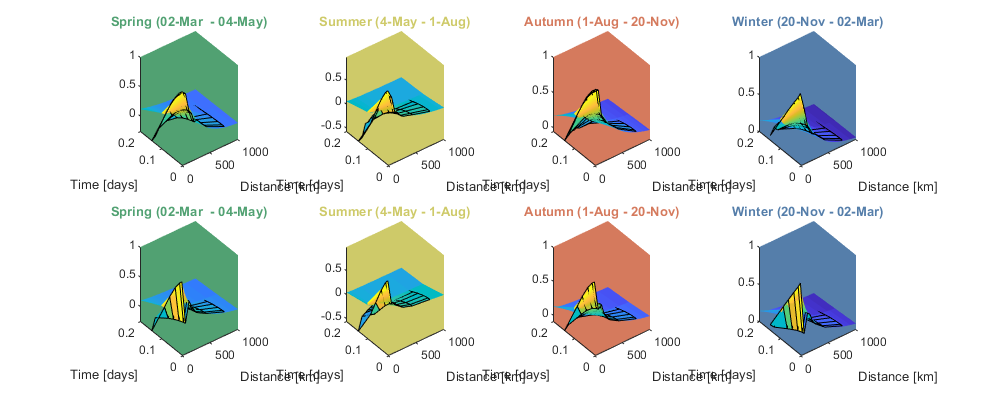

[tmpD,tmpT] = meshgrid(cov.d(1):1:cov.d(end),cov.t(1):0.1:cov.t(end));

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,4,i_b); hold on
    s=surf(tmpD,tmpT,wintra.cov.C_u(tmpD, tmpT,i_b)); s.EdgeColor='none';
    surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    subplot(2,4,i_b,'color',data.block.col(i_b,:)); view(3)
    
    subplot(2,4,4+i_b);  hold on
    s=surf(tmpD,tmpT,wintra.cov.C_v(tmpD, tmpT,i_b)); s.EdgeColor='none';
    surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid_v(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    subplot(2,4,4+i_b,'color',data.block.col(i_b,:)); view(3)
end

## 5. Save

Save the parameters of the model. 

save('data/Wind_inference.mat','wmulti','wintra','-v7.3')


Interpolation Scatter natural

Compute the mean altitude at the radar location

dens_lim=1; %bird/km^3 Minimum density to keep data
alt_mean = nan(numel(dc(1).time),  numel(dc));
for i_d=1:numel(dc)
    tmp = dc(i_d).dens3;
    tmp(:,1:dc(i_d).scatter_lim-1) = mean(MPS{i_d}(:,1:dc(i_d).scatter_lim-1,:),3);
    tmp = tmp .* repmat(min(max(dc(1).alt-dc(i_d).heightDEM,0),200)/200,size(tmp,1),1);
    
    tmp(any(isnan(tmp),2),:) = nan;
    tmp(sum(tmp(:,dc(i_d).scatter_lim:end)*.2,2)<dens_lim,:) = nan;
    alt_mean(:,i_d) = sum(tmp .* repmat(dc(1).alt,size(tmp,1),1),2) ./ sum(tmp,2);
    
    % locate altitude with highest value
    [~,id] = max(tmp,[],2);
    alt_max(:,i_d) = dc(1).alt(id);
    
% Compute quantile instead of mean.    
%     tmp2 = cumsum(tmp,2)./sum(tmp,2);
%     for i_t = 1:size(tmp,1)
%         id = diff(tmp2(i_t,:))>0
%         if ~isnan(tmp2(i_t,1))
%             median_alt(i_t) = interp1(tmp2(i_t,id),dc(i_d).alt(id),.5);
%         end
%     end
end

Remove nan data to be same size as data

alt_mean(data.id_t,:)=[];
alt_mean(data.NNT<-1 | data.NNT>1)=nan;

Normalized with DEM

altn=alt_mean-repmat(data.heightDEM',size(alt_mean,1),1);

Fgiure

figure('position',[0 0 1000 400]); plot(data.time, altn)
ratio_coord_time = 13;   
[ID,T] = meshgrid(1:data.nrad,datenum(data.time));

Fn = scatteredInterpolant(data.lat(ID(~isnan(altn))), data.lon(ID(~isnan(altn))), T(~isnan(altn)).*ratio_coord_time, altn(~isnan(altn)),'natural');
g_alt= nan(g.nlm,g.nt);
tic
for i_d=1:g.nat
    id = g.day_id==i_d;
    g_alt(:,id) = Fn( repmat(g.lat2D(g.latlonmask),1,sum(id)), repmat(g.lon2D(g.latlonmask),1,sum(id)), repmat(datenum(g.time(id))',g.nlm,1).*ratio_coord_time );
    toc
    
end

g_alt_2 = nan(g.nlat,g.nlon,57);
g_alt_2(repmat(g.latlonmask,1,1,57))=g_alt;

figure; imagesc(g_alt_2(:,:,4))
